# Optimising an open top Box

## Minimising the Surface Area

The aim is to minimise the surface area of an open top box, given it has a fixed volume $V$.

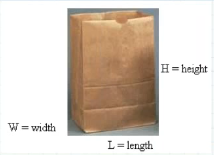

The surface area of this box is shown below (it has no top surface)

syms W L H A V real positive
eqSA = A == W*L+2*W*H+2*H*L

$$eqSA = A=L\,W+2\,H\,L+2\,H\,W$$

The volume enclosed by the box is shown below

eqVol = V == W*L*H

$$eqVol = V=H\,L\,W$$

To minimise the surface area of the box, we need to solve the jacobian $\frac{\partial(SA)}{\partial(L)}, \frac{\partial(SA)}{\partial(W)},\frac{\partial(SA)}{\partial(H)} = 0$. However $H$ is a function of the other two due to the volume equation, as we are using a fixed volume, so we'll substitute that out:

eqSAcons = subs(eqSA,H,rhs(isolate(eqVol,H)))

$$eqSAcons = A=L\,W+\frac{2\,V}{L}+\frac{2\,V}{W}$$

eqdSAconsdW = diff(eqSAcons,W)

$$eqdSAconsdW = 0=L-\frac{2\,V}{W^{2}}$$

eqdSAconsdL = diff(eqSAcons,L)

$$eqdSAconsdL = 0=W-\frac{2\,V}{L^{2}}$$

Solving the above equations, we get the following relationships between the length,width,height; and the volume.

vars = solve({eqVol,eqdSAconsdW,eqdSAconsdL},{L,W,H});
L == vars.L

$$ans = L=2\,{\left(\frac{V}{4}\right)}^{1/3}$$

W == vars.W

$$ans = W=2\,{\left(\frac{V}{4}\right)}^{1/3}$$

H == vars.H

$$ans = H={\left(\frac{V}{4}\right)}^{1/3}$$

eqSubs(vars.L,V,1.5*u.ft^3,u.in,4)

$$ans = 17.31\,\mathrm{in}$$

eqSubs(vars.H,V,1.5*u.ft^3,u.in,4)

$$ans = 8.653\,\mathrm{in}$$

Substituting in those relationships into the original surface area equation, we get the following when the area is minimised:

eqAV = simplify(subs(eqSA,{L,W,H},{vars.L,vars.W,vars.H}))

$$eqAV = 3\,2^{2/3}\,V^{2/3}=A$$

eqSubs(eqAV,V,1.5*u.ft^3,u.ft,4)

$$ans = A=6.24\,{\mathrm{ft}}^{2}$$

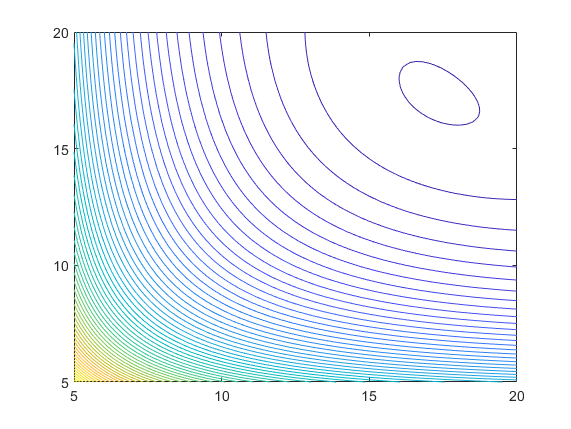

fcontour(subs(SAcons,V,separateUnits(unitConvert((1.5*u.ft^3),u.in))),[5,20,5,20],'LevelStep',20)

## Maximising volume for a given surface area

eqVol

$$eqVol = V=H\,L\,W$$

eqSA

$$eqSA = A=L\,W+2\,H\,L+2\,H\,W$$

We need to differentiate the volume, but again, the height is a function of the length and width, so we substitute it out.

eqVolcons = subs(eqVol,H,rhs(isolate(eqSA,H)))

$$eqVolcons = V=\frac{L\,W\,\left(A-L\,W\right)}{2\,L+2\,W}$$

Solving the jacobian = 0 gives the following relationships between the length,width,height; and the area.

maxvolVars = solve({diff(eqVolcons,L),diff(eqVolcons,W),eqSA});
L == maxvolVars.L

$$ans = L=\frac{\sqrt{3}\,\sqrt{A}}{3}$$

W == maxvolVars.W

$$ans = W=\frac{\sqrt{3}\,\sqrt{A}}{3}$$

H == maxvolVars.H

$$ans = H=\frac{\sqrt{3}\,\sqrt{A}}{6}$$

eqAV = subs(eqVol,{L,W,H},{maxvolVars.L,maxvolVars.W,maxvolVars.H})

$$eqAV = V=\frac{\sqrt{3}\,A^{3/2}}{18}$$

simplify(isolate(eqAV,A))

$$ans = A=3\,2^{2/3}\,V^{2/3}$$

Which is the same result as before.

function exout = eqSubs(exin, symbols, values, units, precision)
    exout = vpa(simplify(unitConvert(subs(exin,symbols,values),units)),precision);
end